# Parameters for simulation of a Differential Drive Mobile Robot:

This script defines model parameters into the base MATLAB workspace.  These parameters are used by the Simulink models of the Differential Drive Robot (DDR).  The equations of motion of the DDR are derived in the script called <bh_DDR_model_EOM_derivation.mlx>. 

After defining the DDR model parameters, you can open and run the Simulink model:

- `bh_DDR_system_model.slx`

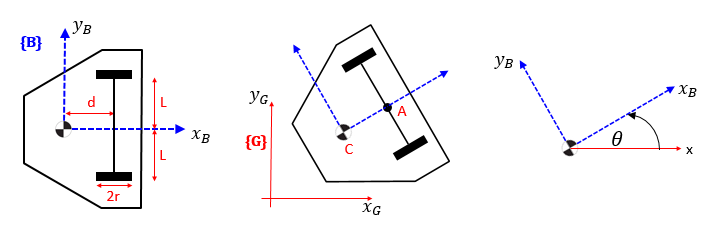

`Bradley Horton : 01-Mar-2016, bradley.horton@mathworks.com.au`

## Vehicle GEOMETRY and INERTIA:

## 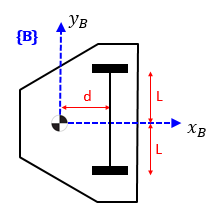

% Vehicle geometry
veh.L_full_axle  = 0.11;              % m (bh ruler measured)
veh.L_half_axle  = veh.L_full_axle/2; % m
veh.d            = 0.07;              % m

%% Vehicle MASS properties
veh.mass    = 0.3;   % kg
veh.Inertia = 0.01;  % kg.m^2

## Vehicle STATES:

veh.states.init_vel_B_Cx       = 0;    % m/sec
veh.states.init_theta_pos_deg  = 0;    % deg
veh.states.init_theta_vel_deg  = 0;    % deg/sec
veh.states.init_pos_G_Cxy      = [0;0];    % m
veh.states.init_pose           = [veh.states.init_pos_G_Cxy(:);
                                  veh.states.init_theta_pos_deg*(pi/180)];

## WHEELS:

veh.wheel.r      = 2.8/100;     % m (bh ruler measured)
veh.wheel.mass   = 30/1000;     % kg
veh.wheel.I      = 1.1760e-04   % kg.m^2

veh = struct with fields:
    L_full_axle: 0.1100
    L_half_axle: 0.0550
              d: 0.0700
           mass: 0.3000
        Inertia: 0.0100
         states: [1×1 struct]
          wheel: [1×1 struct]


veh.wheel.bR     = 4.1142324090730581E-7;   % N.m.s
veh.wheel.bL     = 4.1142324090730581E-7;   % N.m.s

## MOTOR:

%% define the TUNED motor parameter values
mot_B.B = 4.1142324090730581E-7;   % N.m.s
mot_B.J = 4.9413466836860654E-7;   % kg.m^2
mot_B.K = 40*0.010032067085177612; % N.m/A
mot_B.Kb = mot_B.K;                % V.s/rad
mot_B.L = 0.00035576552657332907;  % Henry
mot_B.R = 15.861726606225663;      % Ohms

mot_C.B = 6.1501053292786236E-7;
mot_C.J = 2.982333889011485E-7;
mot_C.K = 40*0.00845442942316282;
mot_C.Kb = mot_C.K;
mot_C.L = 0.00011491242071213385;
mot_C.R = 20.919448570915677;

%% COMMON MOTOR params
mot_COM.Vmax_sat =  7.4;  % volts
mot_COM.Vmin_sat = -7.4;  % volts
mot_COM.w_max    = 17;    % rad/sec

## Racetrack Paths:

Paths in the Excel file include:

- `MEDIUM_S_HOME, SMALL_S_HOME`

- `RECT_TRI, SQUARE, CIRCLE_HOME`

- `L_AND_R_TURNS, SPANNER`

THE_SHEET = 'SQUARE';
my_path_data_T = readtable('bh_robot_paths.xlsx', 'Sheet', THE_SHEET)

my_path_data_T = 5×2 table
    X     Y 
    _    ___

    0      0
    1      0
    1      1
    0      1
    0    0.2



% figure; 
% plot(my_path_data_T.X, my_path_data_T.Y, '-r.', 'LineWidth', 3, 'MarkerSize',20);
% axis tight; grid on; xlabel('X (m)'); ylabel('Y (m)')

##  ATTENTION:

If your Simulink model has an optional "Race_Track_Selector" block inside it, then this block will take precedance in defining the following parameters:

- `my_path_data_T`

- `pp_cont.Waypoints `

## Controllers:

%% sample time for DISCRETE time components of model
dt = 0.01;  %0.01
Ts = dt;
pp_cont = [];
%pp_cont = robotics.PurePursuit;  %robotics.PurePursuit;

% Determine how the robot behaves at corner, generally larger than velocity
% As a general rule, the lookahead distance should be larger than the desired
% linear velocity for a smooth path. The robot might cut corners when the
% lookahead distance is large. In contrast, a small lookahead distance can
% result in an unstable path following behavior. A value of 0.6 m was chosen
% for this example.  
pp_cont.LookaheadDistance     = 0.2;        % m 
pp_cont.DesiredLinearVelocity = 0.1;        % m/s
pp_cont.MaxAngularVelocity    = 60*pi/180;  %radians/second     
pp_cont.Waypoints             = [my_path_data_T.X,  my_path_data_T.Y ];

##  ATTENTION:

If your Simulink model has an optional "Race_Track_Selector" block inside it, then this block will take precedance in defining the following parameters:

- `pp_cont.LookaheadDistance`

- `pp_cont.DesiredLinearVelocity`

- `pp_cont.MaxAngularVelocity`

- `pp_cont.Waypoints `

## BUS signal interface for COMPONENT model:

bh_create_BUS_objects()